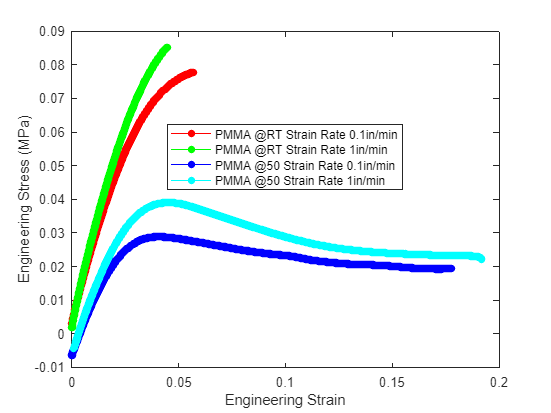

% THIS SCRIPT CALCULATES AND PLOTS THE EGR STRESS AND STRAIN FOR PMMA AND PLOTS THEM
% HERE'S SOME MATLAB TIPS TO HELP:
% Firstly, be sure to paste this code into a New Live Script, way easier to
% work here than directly in the Command Window
% Semicolons keeps variables from being outputted when they're created,
% makes it easy to keep your outputs clean and check variables when needed
% Select multiple lines and use CTRL+R to make them all comments!
% ATTRIBUTION: ChatGPT, Mathworks.com, adapted from my Lab02 Code

% Open .csv file and retrieve data
PMMA = '/Users/vinay/Downloads/PMMA_S6_1 (2).csv';
PMMA_data = readtable(PMMA_rt1,'HeaderLines',13);

% Define material properties
PMMA_rt1_width = 13.21;
PMMA_rt1_thickness = 3.07;
PMMA_rt1_length = 89.18;

PMMA_rt2_width = 13.16;
PMMA_rt2_thickness = 3.2;
PMMA_rt2_length = 92.38;

PMMA_501_width = 12.57;
PMMA_501_thickness = 3.25;
PMMA_501_length = 90.65;

PMMA_502_width = 13.03;
PMMA_502_thickness = 3.2;
PMMA_502_length = 91.26;

rate1 = 2.54;
rate2 = 25.4;

% Extract data from tables, be careful here to use correct indices
% Likely have to scan through csv file to obtain correct indices
PMMA_rt1_time = PMMA_data{1:5995, 2};
PMMA_rt1_displacement = PMMA_data{1:5995, 3};
PMMA_rt1_force = PMMA_data{1:5995, 4};

PMMA_rt2_time = PMMA_data{6004:6493, 2};
PMMA_rt2_displacement = PMMA_data{6004:6493, 3};
PMMA_rt2_force = PMMA_data{6004:6493, 4};

PMMA_501_time = PMMA_data{6501:25572, 2};
PMMA_501_displacement = PMMA_data{6501:25572, 3};
PMMA_501_force = PMMA_data{6501:25572, 4};

PMMA_502_time = PMMA_data{25574:27632, 2};
PMMA_502_displacement = PMMA_data{25574:27632, 3};
PMMA_502_force = PMMA_data{25574:27632, 4};

% Calculate engineering stress and strain values for each material,
% tabularize because it's easy to troubleshoot by displaying the tables
PMMA_rt1_egrstress = PMMA_rt1_force ./ (PMMA_rt1_width * PMMA_rt1_thickness);
PMMA_rt1_egrstrain = PMMA_rt1_displacement ./ PMMA_rt1_length;
PMMA_rt1_table = table(PMMA_rt1_time,PMMA_rt1_egrstrain,PMMA_rt1_egrstress);

PMMA_rt2_egrstress = PMMA_rt2_force ./ (PMMA_rt2_width * PMMA_rt2_thickness);
PMMA_rt2_egrstrain = PMMA_rt2_displacement ./ PMMA_rt2_length;
PMMA_rt2_table = table(PMMA_rt2_time,PMMA_rt2_egrstrain,PMMA_rt2_egrstress);

PMMA_501_egrstress = PMMA_501_force ./ (PMMA_501_width * PMMA_501_thickness);
PMMA_501_egrstrain = PMMA_501_displacement ./ PMMA_501_length;
PMMA_501_table = table(PMMA_501_time,PMMA_501_egrstrain,PMMA_501_egrstress);

PMMA_502_egrstress = PMMA_502_force ./ (PMMA_502_width * PMMA_502_thickness);
PMMA_502_egrstrain = PMMA_502_displacement ./ PMMA_502_length;
PMMA_502_table = table(PMMA_502_time,PMMA_502_egrstrain,PMMA_502_egrstress);

% Plot the data for each material, plot of points with line connecting them
plot(PMMA_rt1_egrstrain, PMMA_rt1_egrstress, 'r-o', 'MarkerFaceColor', 'red','MarkerSize', 5);
hold on
plot(PMMA_rt2_egrstrain, PMMA_rt2_egrstress, 'g-o', 'MarkerFaceColor', 'green','MarkerSize', 5);
plot(PMMA_501_egrstrain, PMMA_501_egrstress, 'b-o', 'MarkerFaceColor', 'blue','MarkerSize', 5);
plot(PMMA_502_egrstrain, PMMA_502_egrstress, 'c-o', 'MarkerFaceColor', 'cyan','MarkerSize', 5);

xlabel('Engineering Strain');
ylabel('Engineering Stress (MPa)');
legend('PMMA @RT Strain Rate 0.1in/min','PMMA @RT Strain Rate 1in/min','PMMA @50 Strain Rate 0.1in/min','PMMA @50 Strain Rate 1in/min','Location','best');

hold off